chaotic(0, [1 2 3])

ans =     10
    23
    -6


X1 = [-2.04; -3.5; 21];
X2 = 0.99*X1;
t = 0;
sol1 = ode45(@(t,y) chaotic(t, y), [0 5], X)

sol1 = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [1×72 double]
          y: [3×72 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


sol2 = ode45(@(t,y) chaotic(t, y), [0 5], X2)

sol2 = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [1×76 double]
          y: [3×76 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


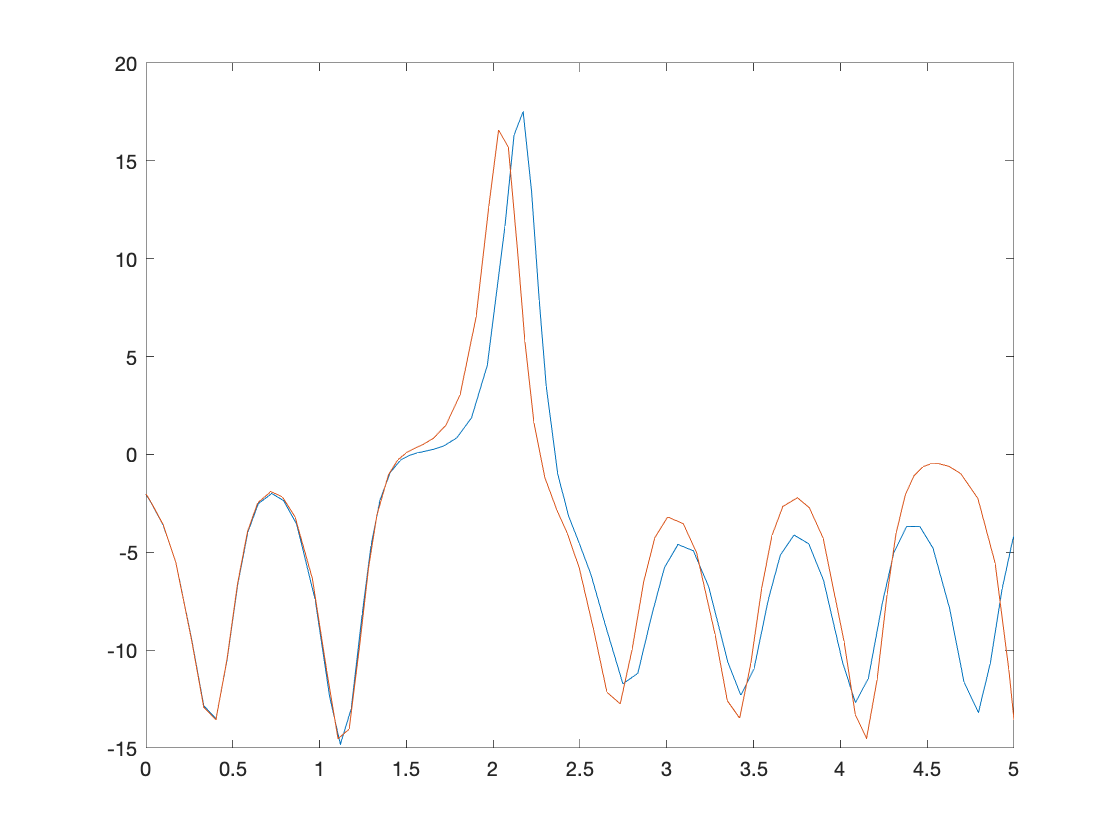


plot(sol1.x, sol1.y(1,:), sol2.x, sol2.y(1,:))

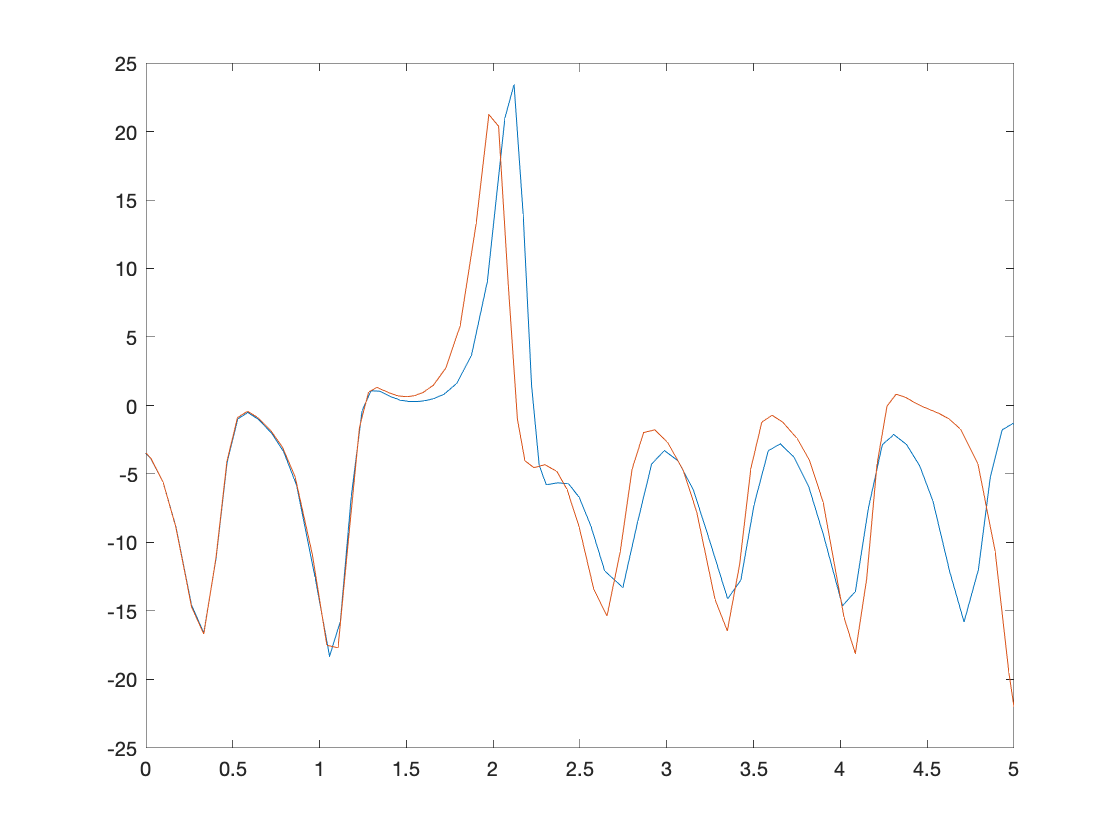

plot(sol1.x, sol1.y(2,:), sol2.x, sol2.y(2,:))

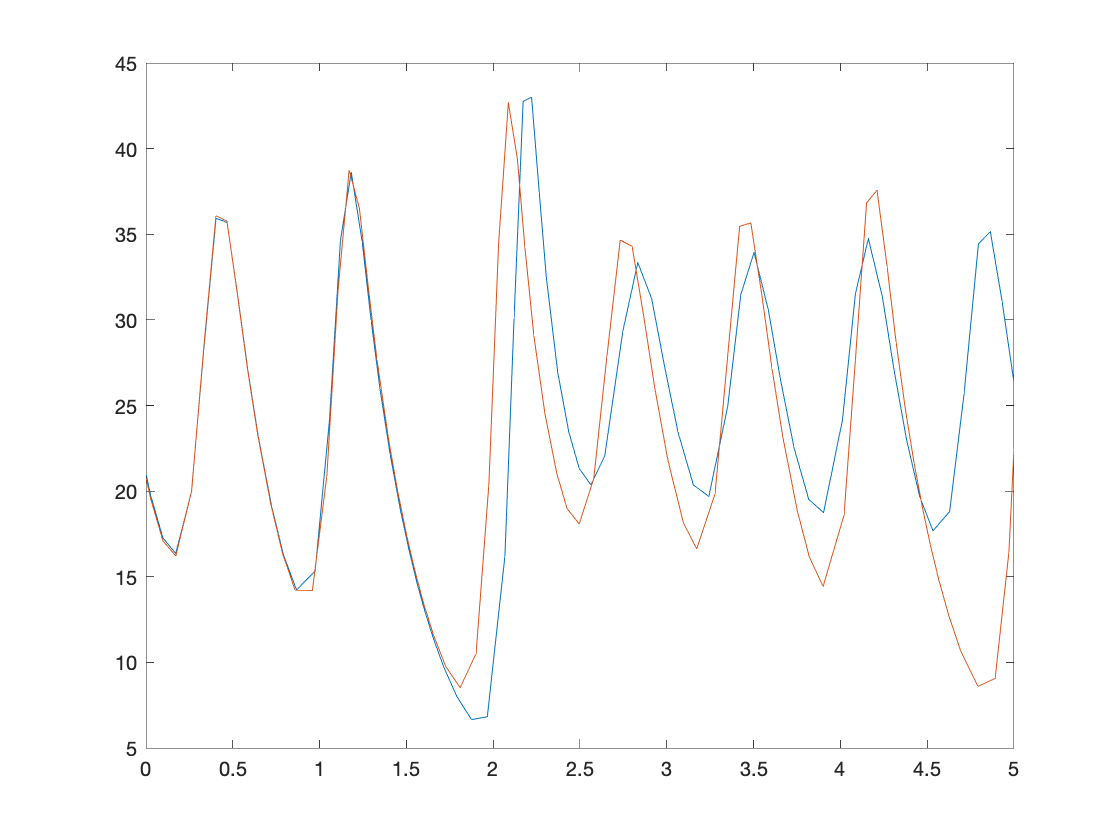

plot(sol1.x, sol1.y(3,:), sol2.x, sol2.y(3,:))